%% Script Ελέγχου για την 5.2.1 (Test IEEE 14)
clc; clear;

% 1. Ορίζουμε τα δεδομένα εισόδου (όπως στο παράδειγμα του IEEE 14)
nBus = 14; 

% Τα δεδομένα γραμμών (Από Κόμβο -> Προς Κόμβο)
lineData = [
    1 2; 1 5; 2 3; 2 4; 2 5; 3 4; 4 5; 4 7; 4 9; 5 6;
    6 11; 6 12; 6 13; 7 8; 7 9; 9 10; 9 14; 10 11; 12 13; 13 14
];

% 2. ΚΑΛΟΥΜΕ τη συνάρτηση που έφτιαξες
% Της δίνουμε τα lineData και το nBus και παίρνουμε πίσω το A
A = createConnectivityMatrix(lineData, nBus);

Connectivity Matrix Created: 14x14



% 3. Εμφάνιση αποτελέσματος
disp('Ο Πίνακας Συνδεσιμότητας (A) δημιουργήθηκε:');

Ο Πίνακας Συνδεσιμότητας (A) δημιουργήθηκε:


disp(A);

     1     1     0     0     1     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     0     0     0     0     0     0     0     0     0
     0     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     0     1     0     1     0     0     0     0     0
     1     1     0     1     1     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0     1     1     1     0
     0     0     0     1     0     0     1     1     1     0     0     0     0     0
     0     0     0     0     0     0     1     1     0     0     0     0     0     0
     0     0     0     1     0     0     1     0     1     1     0     0     0     1
     0     0     0     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     0     0     1     0     0     0     1     1     0     0     0
     0     0     0     0     0     1     0     0     0     0     

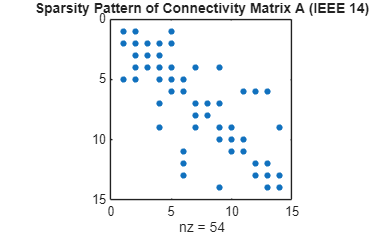


% (Προαιρετικό) Έλεγχος με spy plot για να δεις τη μορφή του
figure;
spy(A);
title('Sparsity Pattern of Connectivity Matrix A (IEEE 14)');